clc,clear all,close all;
syms x_1 x_2 x_3 x_4 x_5 x_6 x_7 omega as real;
M=[x_1,0;...
   0,x_2]

$$M = \left(\begin{array}{cc} x_{1} & 0\\ 0 & x_{2} \end{array}\right)$$


B=inv(M)

$$B = \left(\begin{array}{cc} \frac{1}{x_{1}} & 0\\ 0 & \frac{1}{x_{2}} \end{array}\right)$$


C=[x_3,x_4+x_5*omega;...
    x_6*omega,x_7]

$$C = \left(\begin{array}{cc} x_{3} & x_{4}+\omega \,x_{5}\\ \omega \,x_{6} & x_{7} \end{array}\right)$$

A=-simplify(inv(M)*C)

$$A = \left(\begin{array}{cc} -\frac{x_{3}}{x_{1}} & -\frac{x_{4}+\omega \,x_{5}}{x_{1}}\\ -\frac{\omega \,x_{6}}{x_{2}} & -\frac{x_{7}}{x_{2}} \end{array}\right)$$

num=[25]

num = 25

den=[1 25]

den =      1    25


G=tf(num,den)


G =
 
    25
  ------
  s + 25
 
Continuous-time transfer function.



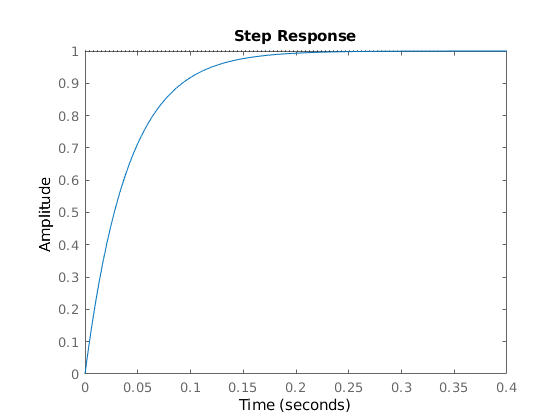

step(G)

[As,Bs,Cs,Ds]=tf2ss(num,den)

As = -25

Bs = 1

Cs = 25

Ds = 0

Gs=ss(As,Bs,Cs,Ds)


Gs =
 
  A = 
        x1
   x1  -25
 
  B = 
       u1
   x1   1
 
  C = 
       x1
   y1  25
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



step(Gs)